# Chemical Process Optimization

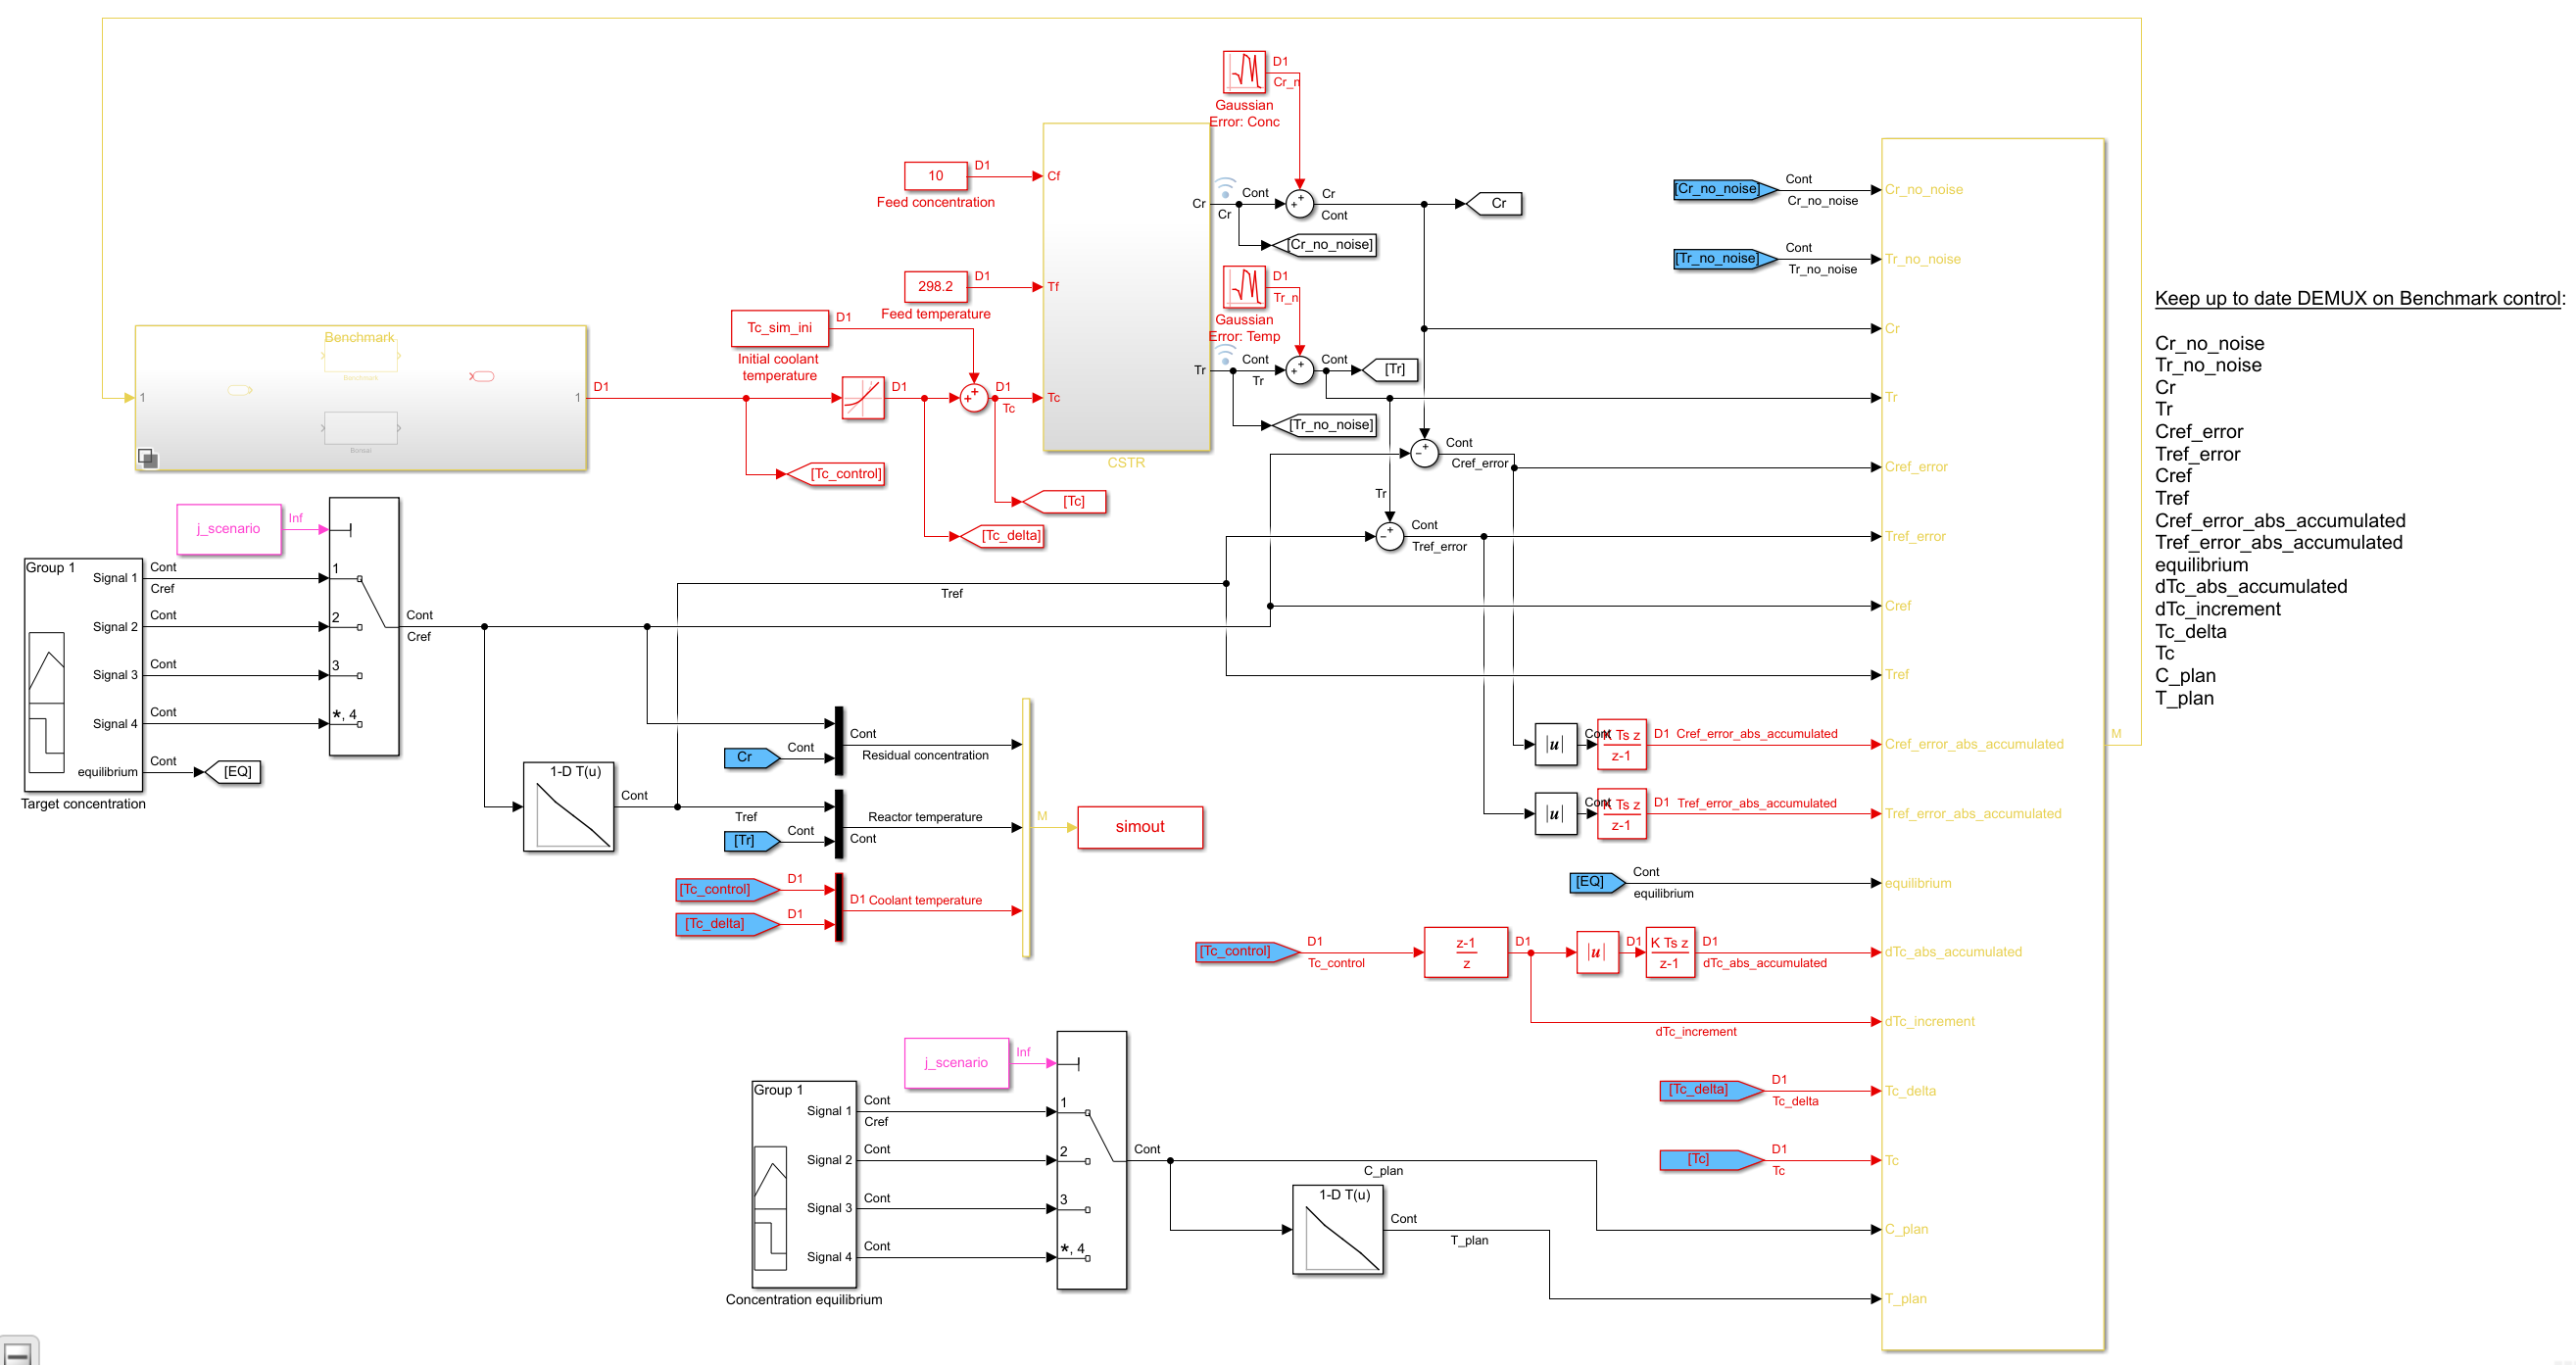

## Model Overview

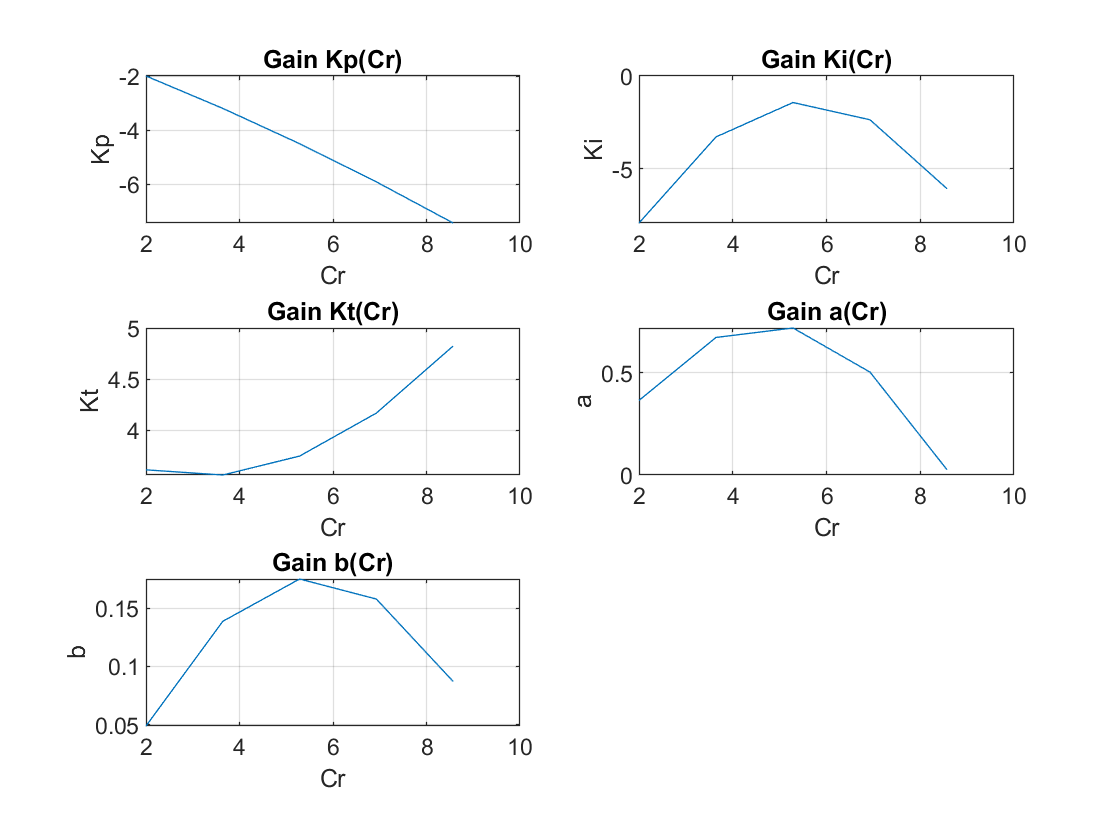

Train a single concept to replace both the gain scheduled PI controller outer loop and lead compensator controller inner loop for transitioning  the Residual Concentration, `Cr` without thermal runaway. The process dynamics is complex because nonlinearities and instablities  exist when manipulating the coolant Temperature, `Tc`.

The following products are required to run the model:

- Simulink Version 10.0 (R2019b) or greater

- Bonsai [Toolbox](http://aka.ms/as/bonsai-toolbox) 0.1.4

- Bonsai [account](https://docs.microsoft.com/en-us/bonsai/quickstart/setup)

startup_MOAB;

% initialize variables
initializeMoab;

% loop the model in Mechanics Explorer
% will compile the model and run 10 loops
runMoabLocalLoop;

% add workspace id
% add access key

edit bonsaiConfig;


bonsaiTrain; 

## Zip, Upload and Scale Your Model

Scaling the model greatly improves training times. Once you have verified your model connects locally, you can close Simulink and zip the entire contents of the folder that contains the model. 

Then you only need to zip the parent **moab** folder. It is suggested you remove your` slprj` folder and` .slxc `files before zipping up the folder contents. You also do not need the` moab_log.csv `file`. `Call the file `moab.zip. `

**Note: **The uploaded simulator supports Normal acceleration mode only.

### Upload the Model

Back in the Bonsai UI, next to `Simulators``,` click the `Add sim` button.

This will open a dialog:

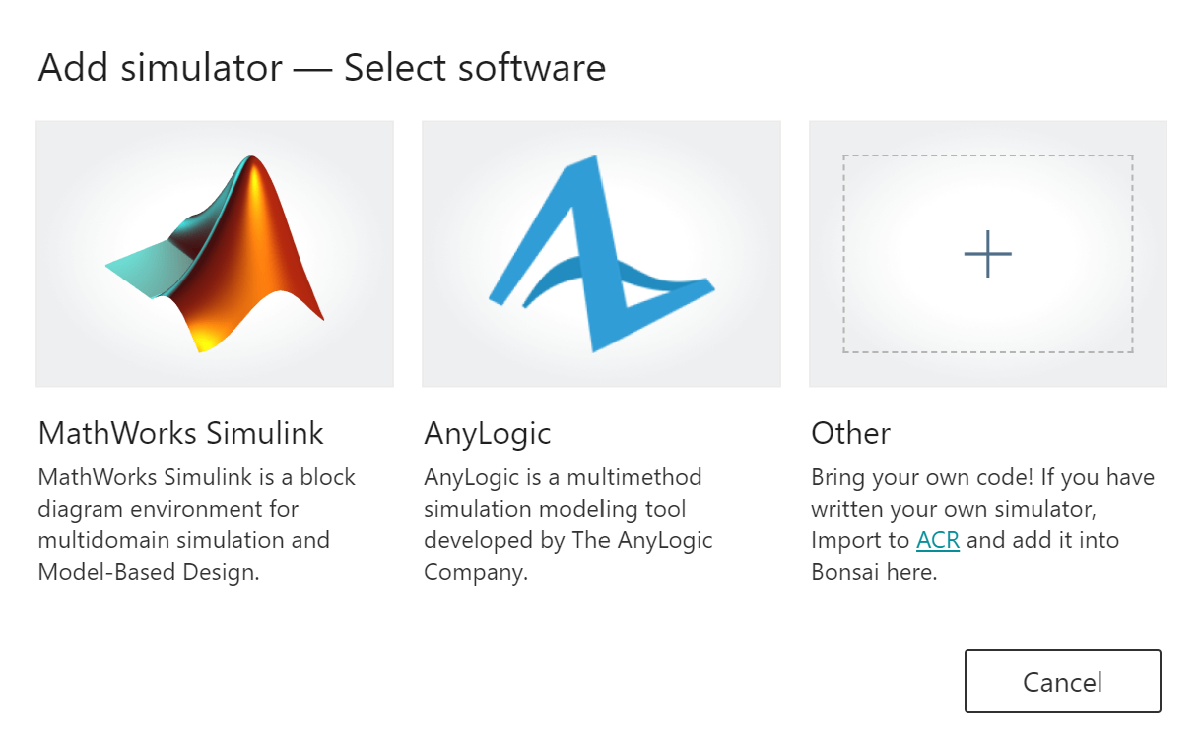

Select `MathWorks``. `Then you can upload your zip file`:`

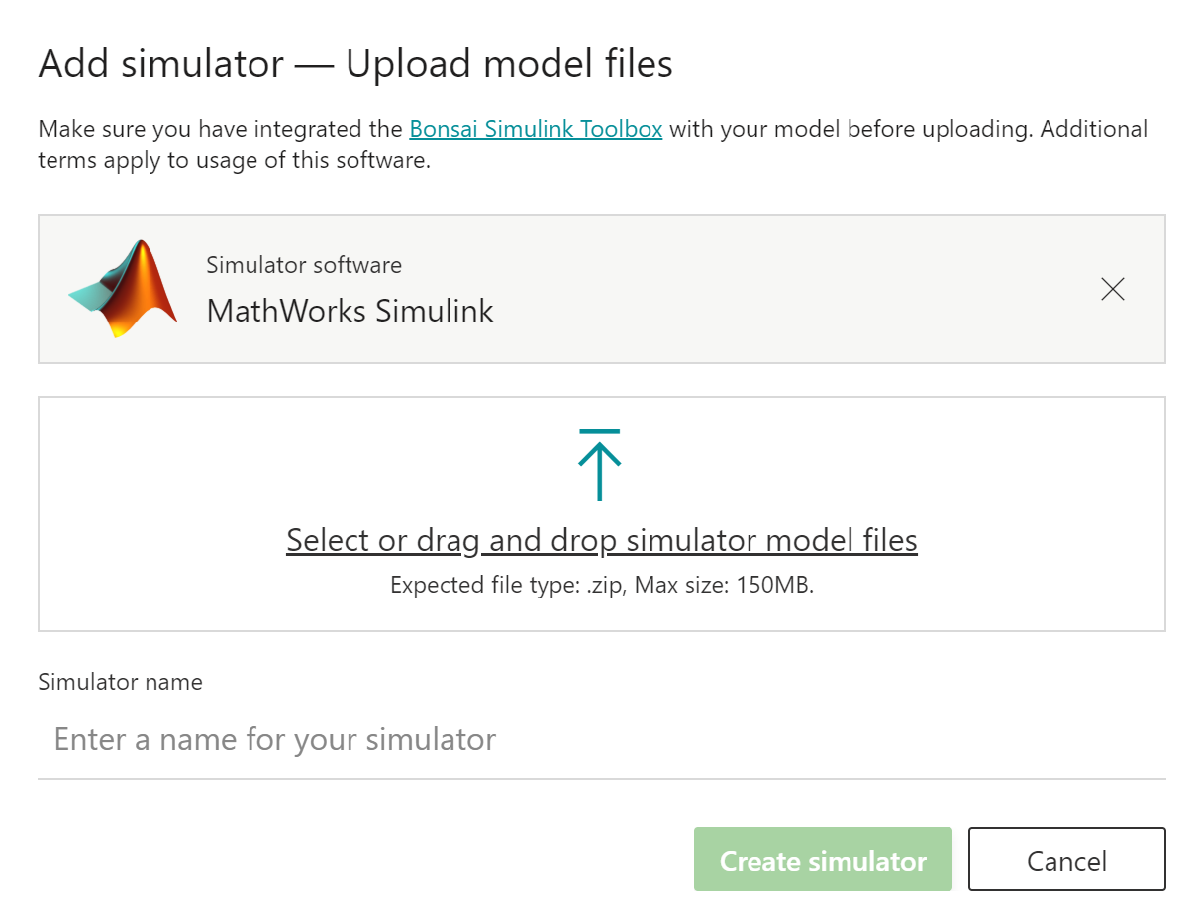

Select or drag the `moab.zip `file created previously`. `

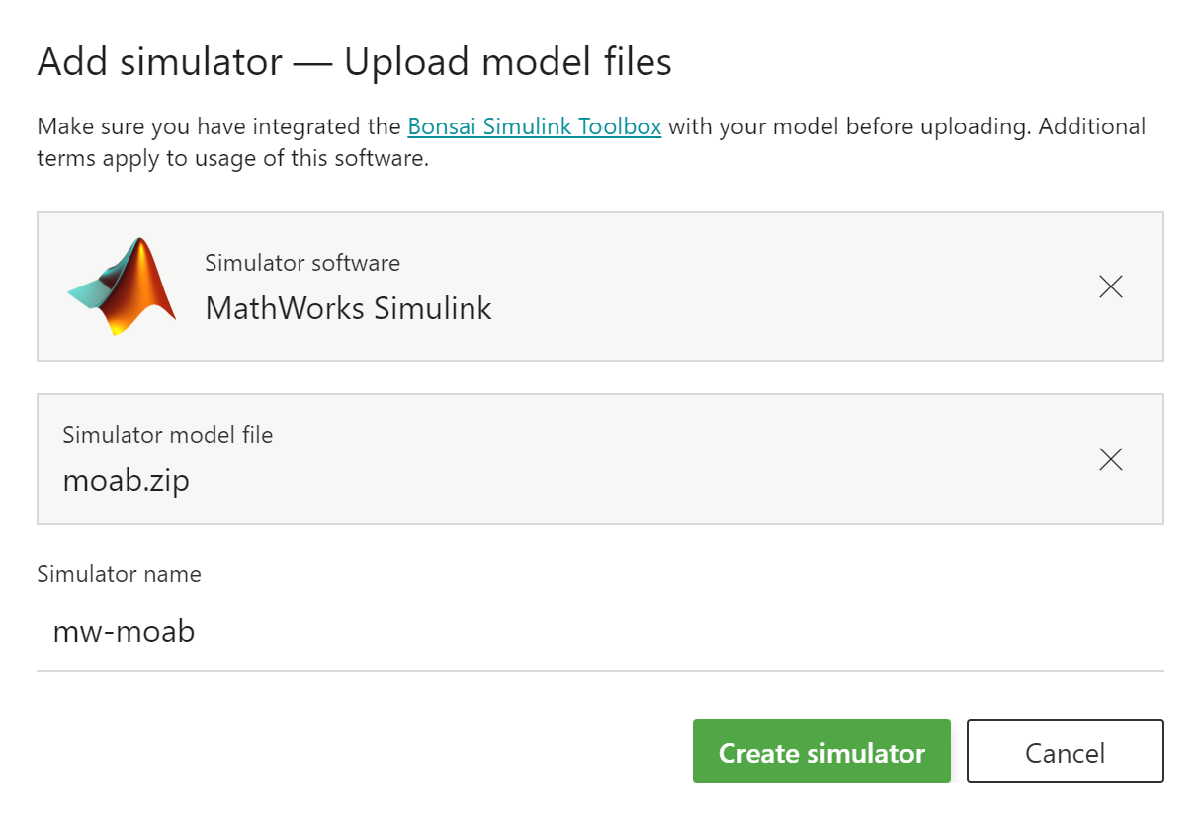

Give your simulator a name, then click `Create simulator``. `

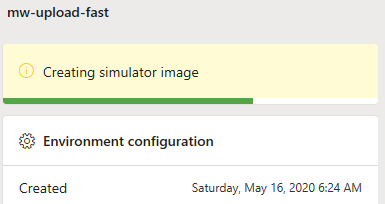

**Note: ***It may take up to 20 minutes to create the simulator image. *You will the ACR path displayed after successful creation:

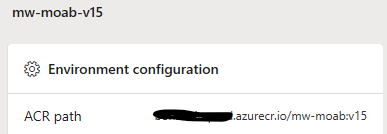

After the simulator is created you will see the new simulator appear under the `Simulators`` section.`

**Note: **Be sure your brain is not training prior to changing the package statement.

Now click the `Teach` tab. 

In the simulator definition, just after the open brackets, add back the package statement using the name of the simulator you gave during the Add Simulator dialog above.

### Scale Your Training

Now click the `Train` button for your brain. This will create several instances (from 1-50) using your uploaded model to train your brain.

**Note: **It may take up to 10 minutes for your simulators to connect.

## Assessing Brain Performance

Assessment allows you to test the performance of a trained brain while still hosting that brain in the Bonsai platform. 

After training your brain(s) you will want to assess their performance. Make sure your Bonsai Controller is enabled in Simulink. Run:

bonsaiAssess;

This will begin assessment and connect to the Bonsai platform, similar to training. If your model is not open this will also open the model.

Click the `Run` button in Simulink.

In the Bonsai UI, click the `Start Assessment `button.

Click the `Simulink - Moab` simulator. 

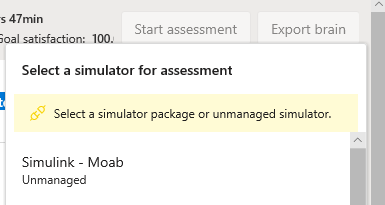

Your local model will iterate using the brain in assessment mode.

If you receive the message `Last event was Unregister, done requesting events `then you may need to increase the timeout value in bonsaiConfig.